## 滑らかな走りを実現するためにはどのように設計をすればよいか

クルマのスムーズな走行を実現するために、さまざまな部品が使われている。

車両の多くの部分が乗客のスムーズな乗り心地の確保に貢献している。

サスペンションシステムには、タイヤ、緩衝器、リンケージといった重要な部品が含まれている。これらが一体となって、路面の凹凸に対する車両の反応を緩和する。

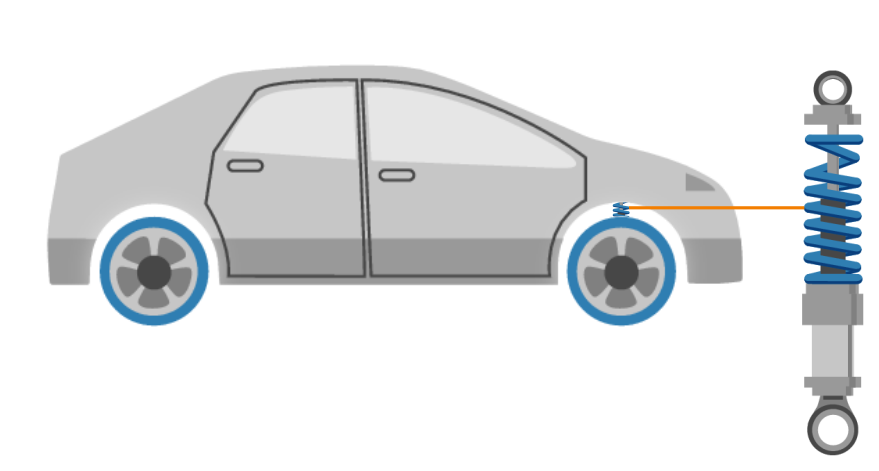

*緩衝器は滑らかな乗り心地を提供し、車両部品の摩耗を軽減する*

緩衝器は、油圧作動液を使って機械的エネルギーを散逸させ、衝撃に対する車両の応答を低減する。車両のコントロール性を維持しつつ、乗り心地を滑らかにするためには、どのように適切な緩衝器を選択すればよいか。その答えは、ダイナミックモデリングにある。このライブスクリプトでは、次のことを行う。

- バネマスダンパーモデルの考察

- Simulinkによるソリューションの解法

- サスペンションモデルのダンピングを設計要件に合わせて調整

 **Pro-tip**: Simulinkを使うことが初めての方は、[Simulink onramp](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink): Simulinkの3時間の無料入門コースの受講をご検討ください。

# The Mass-Spring-Damper

clear % This clears the MATLAB workspace each time you run the script
addModelPaths % This helper adds the model paths

 このセクションを実行してバネ・マスモデルが入っているフォルダーをMATLABサーチパスに追加する。この動作はモデルが実行できる為に必要である。

## 1. バネマスダンパーモデル

バネマスダンパーモデルは、様々な振動物理系に適用できる単純な理想化（モデル）である。その名の通り、バネマスダンパー系には、重り、バネ、ダンパーという3つの理想化された要素が含まれている。

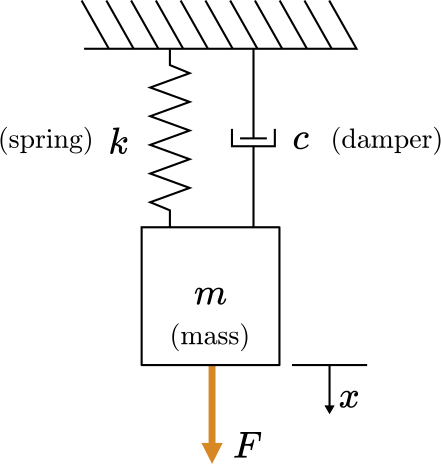

*バネマスダンパー系の模式図 *

いくつかのパラメータによって、この機械システムの動作が決定する。

- $k$: ばね剛性[N/m]

- $c$: 減衰係数 [N$\cdot$s/m]

- $m$: 質量 [kg]

- $F$: 外力 [N] (一定値または時間依存の値: $F(t)$)

システムの時間に依存した挙動を、以下の変数を使って解く。

- $t$: シミュレーションを開始してからの時間  [s]

- $x$: 基準となる平衡位置からの質量の変位(時間に依存する) [m]

- $\dot{x}$: 重りの速度 [m/s]

- $\ddot{x}$: 重りの加速度 [m/s$^2$]

このシステムに力が加わると、重りが振動し始める。機械的エネルギーがダッシュポットによって熱に変換されるため、時間経過とともに振動は減衰していく。

 ** Try**

- 紙の上に, 重り$m$に作用する力の自由物体図(free body diagram)を描く

- 自由物体図(free body diagram)を描いた後、ニュートンの第2法則を適用して運動方程式を導出する 

                $m\ddot{x} \;=\;\;\sum Forces$.

showSolutionFBD = false; % Click the checkbox to view the solution
if(showSolutionFBD)
    I = imread("images/mass_spring_damper_FBD.png");
    imshow(I);
end

#### 車両のサスペンションをバネマスダンパーとしてモデル化

バネマスダンパーは、モデルの構成要素が直接機械部品と対応しているため、緩衝器のモデル化に適している。モデルのバネとダンパーは、それぞれ物理的なバネと衝撃を表している。この2つの要素は、車両を滑らかに平衡状態に戻すための補完的な機能を果たす。

- 緩衝器は、機械的エネルギーを熱として放出する。これにより、（道の）突起物を乗り越えた後の車両全体の動きを抑えることができる。

- バネは衝撃に対する反応を時間的に分散させる。最初の衝撃でバネは圧縮され、その後、規則的な振動が発生する。この振動により、衝撃が機械的エネルギーを散逸する時間が与えられる。

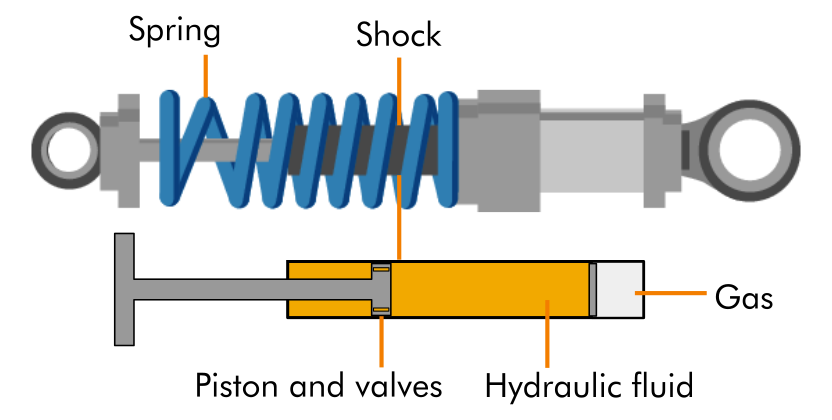

*衝撃/バネシステムの簡略化された模式図。*緩衝器*の内部には、作動油の中を動くピストンがあり、*

*作動油の粘性抵抗により、機械的エネルギーが熱として放出される。*

このスクリプトで使用される単純な理想化では、車両のサスペンション・システム全体（単一の緩衝器ではなく）が、剛性$k$と減衰係数を持つ単一のバネマスダンパーとしてモデル化されている。重りは、車両自体の質量$m$とし、道路のくぼみの上を走行すると、インパルス力$F$が適用される。

 **Reflect**

- 単一のバネマスダンパーシステムで記述されたサスペンションを持つ車両がスピード減速帯を通過したときの自由物体図を描く。

- サスペンション全体に単一のバネマスダンパーシステムを仮定することで、モデルから除外される主要な特徴は何か？

## 2. バネマスダンパー方程式をシンボリック演算で行う

前節で導出したバネマスダンパーの微分方程式は：

    $m\ddot{x} + c \dot{x} + kx =  F$.

Simulinkで常微分方程式(ODE)を解く際には、次のような形式$\ddot{x} = \ldots$にするとよい。

この形式では、解答モデルの構築が簡単になる。ここで$\ddot{x}$を解くには、2つの簡単な代数的ステップだけで良い。しかし、より現実的なモデルシステムでは、通常、同時に解かなければならないいくつかの方程式があり、代数計算が面倒でエラーになりやすい。そのような問題に備えるために、バネマスダンパーのODEでは、$\ddot{x}$をシンボリック演算を使って解くことができる。

  **Pro-tip**:MATLABのシンボリック変数と演算は、通常のMATLABの式とは異なるため、この[ドキュメントページ](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html)でシンボリック変数と式の基本的な構文を少し学んで下さい。

** Exercise. **この練習問題ではシンボリック表記で方程式を定義して、$\ddot{x}$について解く。

**Task 1.** 紙の上で$\ddot{x}$について解く

**Task 2**. x、x_dot、x_ddot、m、c、k、Fの7つのシンボリック変数を以下の空欄に定義する。

MATLABでは、次のコマンド構文を使って複数のシンボリック変数を定義することが可能である。

% Call the syms command here

checkSyms() % This checks if you defined the symbolic variables

**Task 3. **シンボリック変数を使ってバネマスダンパーの方程式を書き、msdEqに代入する。

  **Pro-tip**: シンボリック方程式を書く場合には、=を用いて式全体をMATLABの変数に割り当てる。これは、シンボリック方程式の中の等号は、==を使って書かなければいけないことを意味します。 例えば、

msdEq = NaN % Replace NaN with your equation
checkMSDeq(msdEq) % This helper function (located at the bottom of the script) checks your equation

**Task 4. **[solve(equation, variable)](https://www.mathworks.com/help/symbolic/solve.html)を使用して、バネマスダンパー方程式のx_ddotを解き、その結果をsltnMSDに割り当てる。この構文では、`equation` は解くべきシンボリック方程式で、`variable` は（これについて）解きたいシンボリック変数である。

sltnMSD = NaN % Replace NaN with a call to solve
checkMSDSolve(sltnMSD) % This helper function (located at the bottom of the script) checks your expression

 **Reflect:**

- 4.での解は、1.で手計算した解と一致してるか？

## 3. Simulinkで一次のODEを解く

バネマスダンパーの運動状態を調べる為に、Simulinkでその解を解くことが可能である。2次のバネマスダンパのODEを解く前に、より単純な1次のODEを解くことができる。Simulinkでは、ODEは積分ブロックを使って解くことができる。

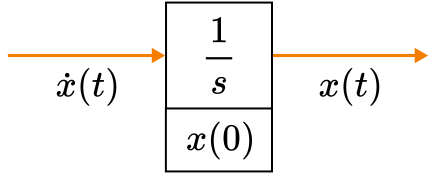

*Simulinkで1次のODEを解くための簡略化されたブロック線図。積分器ブロック（*$1/s$*）は1回積分し、微分の次数を1つ減らす。積分器ブロックは初期条件*$x(0)$を含む*.*

 **Did you know? **時間領域での積分は、ラプラス領域での除算と同じであるため、積分器ブロックには$1/s$のラベルが付けられている。

** Exercise. **ODEを考える:

    
$$\dot{x} = -x$$
 

    $x(0) = 10$ とする

(a) 手計算で解析解を解く。解答を $t$を使って以下に記載。

syms t;
xSltn = NaN; % Replace NaN with your solution in terms of t. Use exp for the exponential.
checkFirstOrder(xSltn)

(b) [新規にSimulinkモデルを作成](matlab: open_system(new_system('simpleODE')))し、以下のようにして下図のソリューションモデルを構築する。

- integratorブロックを追加し、integratorブロックの初期条件を設定する(ブロックをダブルクリックしてダイアログにアクセスする)

- 値を-1に設定したgainブロックを追加する

- scopeブロックを追加する

- 下図のように接続する

- モデルを実行し、scopeをダブルクリックして、出力が(a)で見つけたソリューションと一致することを確認する

 **Pro-tip**: Simulinkキャンバス内の任意の場所をダブルクリックし、追加したいブロックの名前を入力する

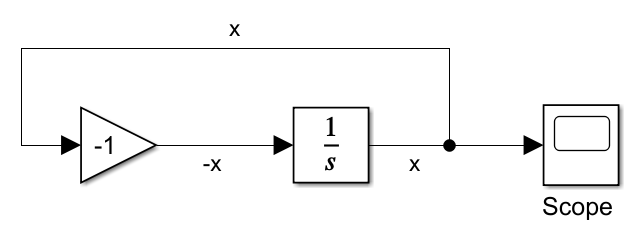

$\dot{x} = -x$ を解くためのSimulink ODEソルバー

 **Reflect:**

- [gainブロック](https://www.mathworks.com/help/simulink/slref/gain.html)の役割は何か？

- integratorブロックへの入力で$-x$が用いられている。なぜintegratorブロックの入力として$-x$が使われているのか？

- integratorブロックの出力は入力にループバックしている。なぜこのようにする必要があるのか？

もし、Simulinkモデルの作成で困ったときは、SimulinkでODEを解く方法について[このブログ記事](https://blogs.mathworks.com/simulink/2008/05/23/how-to-draw-odes-in-simulink/)をご覧ください。

## 4. バネマスダンパーモデルをSimulinkで解く

このセクションでは、Simulinkを使ってバネマスダンパーの2次常微分方程式を解く。

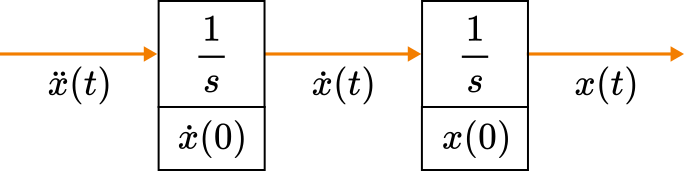

*Simulinkで2次常微分方程式を解くには、2つのintegratorブロックを必要とする*

最初のintegratorブロックに入力を与えるために、$\ddot{x}$を用いる。

    $\ddot{x} = \frac{ F - c \dot{x} - kx}{m}$.

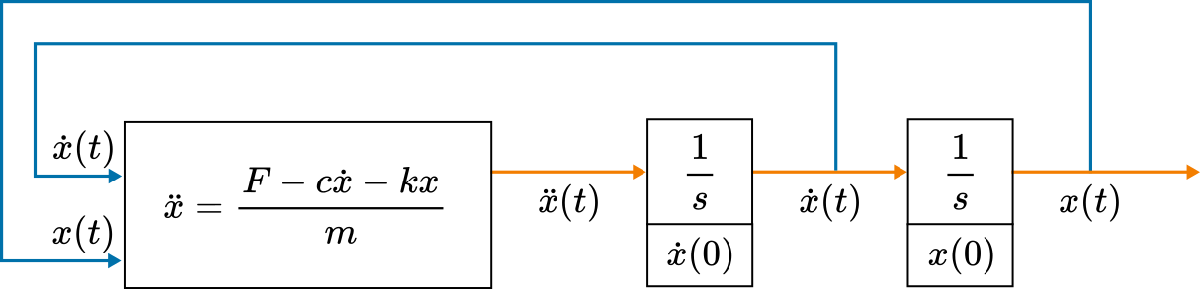

$\ddot{x}$を計算するために必要な入力*(*$\dot{x}$と$x$)はそれぞれintegratorブロックの出力から得られる

先ほど、MATLABの記号計算を使って運動方程式を解いた式を、MATLAB functionブロックに記述することにより、Simulinkに直接移植することができる。

** Exercise. **Simulinkモデル [mfb.slx](matlab: open_system('models/mfb')) を開き、$\ddot{x}$に関するMATLAB表現式を追記してMATLAB Functionブロックを完成させる。

yourExpression = char(sltnMSD) % This displays your expression for x_ddot.

- 上で`x_ddot`についてシンボリック計算したMATLAB表現式を、MATLAB Functionブロック内で使用することができる

- [MATLAB Functionブロック](matlab: hilite_system('mfb/double-click me'); pause(1); hilite_system('mfb/double-click me','none');)をダブルクリックして、MATLABコードを編集する

- モデルを実行して、正しい挙動であるか確認する

** Exercise. **この演習では、バネマスダンパーの常微分方程式をSimulinkで解くモデルを完成させる

2次の常微分方程式を解く計算のために、2つのintegratorブロックが必要である

- [msd.slx](matlab: open_system('models/msd')) を開く

- システムを完成させるために、**Integrator**ブロックを2つ追加し、それらをシステム**に**接続する

- Integratorブロックの初期条件として $\dot{x}(0) = -3$, $x(0)=2$を設定する

- モデルを実行し、出力を確認するために[Scope](matlab: hilite_system('msd/Scope'); pause(1); hilite_system('msd/Scope','none');)をダブルクリックする。 下図の解答と一致すれば、作成したモデルは正しいことになる。

            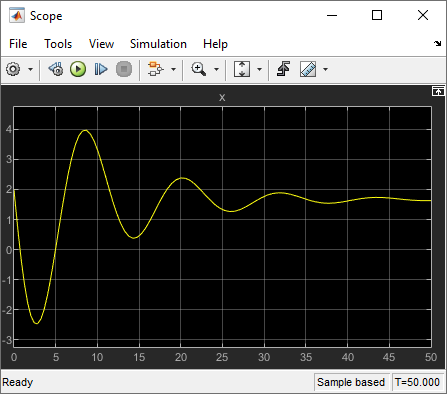

*            バネマスダンパーシステムの解答*

困ったときは、完成したモデル [msdSoln.slx](matlab: open_system('models/msdSoln')). を見ることができる。

**バネマスダンパーの挙動を可視化する**

モデルが完成すると、その系の挙動を可視化することができる。simコマンドは、完成したバネマスダンパーモデル（msdSimulationOutput.slx）のシミュレーションを実行する。ローカル関数 animateMSDは、モデルからの出力のアニメーションを作成する。

n = 150; % The number of steps used in the visualization
visualize = false; % Click the checkbox to show the visualization
if(visualize)
    simOut = sim("models/msdSimulationOutput"); % Run the Simulink model
    animateMSD(simOut.tout,simOut.yout,0.5,n)
end

 ** Try**

Simulinkモデル [msdSimulationOutput.slx](matlab: open_system("models/msdSimulationOutput")) を開き、以下を試してみる。

- 減衰係数を 0に設定した後、スクリプトのこのセクションを再実行する。その際、挙動にどのような影響があるか?

- ばね剛性の値を下げて、アニメーションを再実行する

- モデルの初期条件を調整する。まず，初期位置$x(0)$を変更し，次に初期速度$\dot{x}(0)$を変更する。この時、異なった影響だったか、同じような影響であったか?

## 5. バネマスダンパーモデルによるサスペンション減衰力調整

Simulinkで常微分方程式を解いた後は、それを応用して、単一バネマスダンパーとしてモデル化された車両のサスペンションを調整することができる。

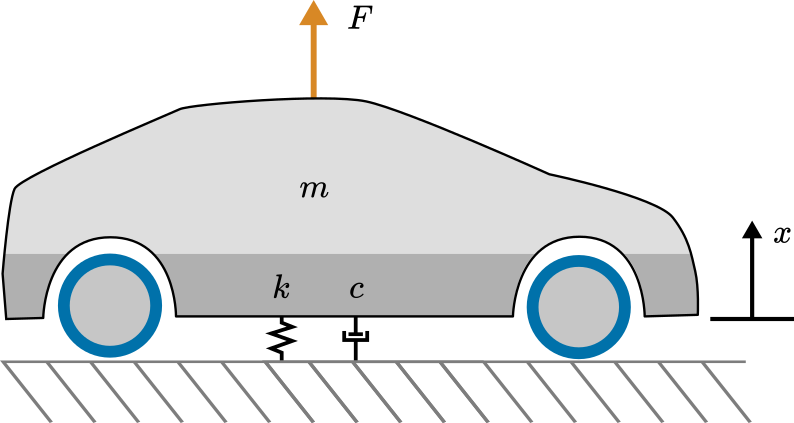

*車両に適用したバネマスダンパーモデルの模式図. 全体のサスペンションは *ばね剛性$k$*, 減衰係数*$c$で表される。静止状態では、車両車台の垂直方向の位置は$x=0$である。

このセクションでの目標は、設計要件を満たすようにサスペンションを調整することである。

** Exercise. **次のような特性を持つ車両を考える。

- Vehicle mass: 1360 kg

- Suspension stiffness: 26,000 N/m

- 車体重量: 1360 kg

- ばね剛性: 26,000 N/m

以下の設計要件を満たすように減衰係数$c$を選択する。道の凸凹に遭遇した結果、9000Nの力が0.1秒加わったとしてモデル化すると、車両は以下の条件を満たす必要がある。

- 衝突後の最大絶対垂直変位が0.1m未満であること

- 1秒後の絶対垂直変位が0.02m以下であること

- 減衰係数は、要件1および2を満たしつつ、可能な限り小さくすること

前提として、初期状態で車両には垂直方向の動きや変位がないものとする。

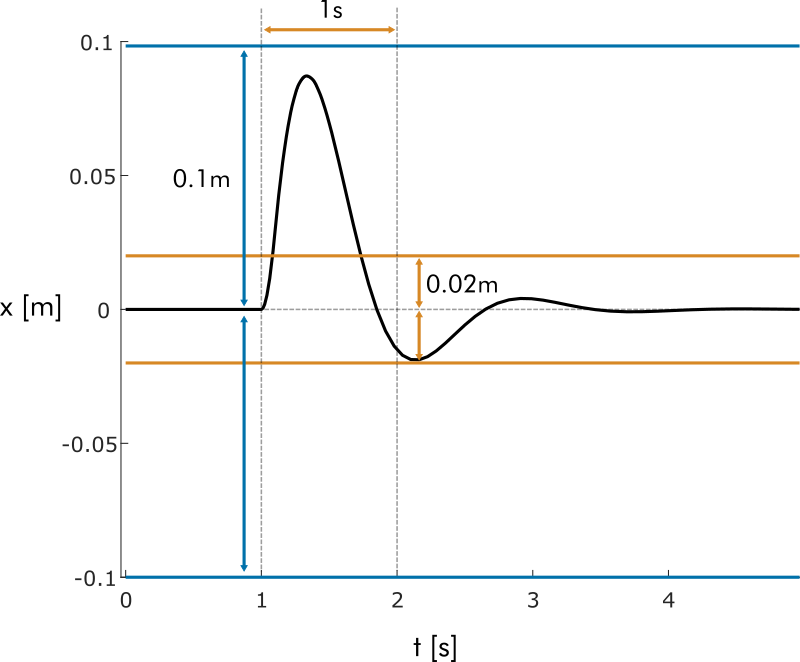

*設計要件の模式図。最初の垂直方向の変位は0.1m以下で、その後の振動振幅は0.02m以下の大きさであること*

 ** Tasks. **要件を満たすように調整するために、以下の作業を行う。

- モデル[msdTune.slx](matlab: open_system('models/msdTune')) を開く。 このモデルには、前のセクションで扱ったバネマスダンパーモデルを含むマスクされたサブシステムがある。矢印マーク( ) をクリックするとマスク内部のモデルを見ることができる。 

- このモデルの[マスク](matlab: hilite_system('msdTune/mass-spring-damper model'); pause(1); hilite_system('msdTune/mass-spring-damper model','none');)をダブルクリックして、初期条件、変位$x(0)$と速度$\dot{x}(0)$を設定する。

- モデルの固定パラメータである [*k*](matlab: hilite_system('msdTune/k'); pause(1); hilite_system('msdTune/k','none');) と [*m*](matlab: hilite_system('msdTune/m'); pause(1); hilite_system('msdTune/m','none');)*を設定する。このモデルは既に正しい衝撃力*$F$*を適用しているので、*"F" のサブシステムを変更しないこと。

- 減衰係数[*c*](matlab: hilite_system('msdTune/c'); pause(1); hilite_system('msdTune/c','none');)を設定し、モデルを実行して車両の跳ね返り現象を[scope](matlab: hilite_system('msdTune/Scope'); pause(1); hilite_system('msdTune/Scope','none');)で確認する。

- この3つの条件が満たされるまで、減衰力調整を行う。

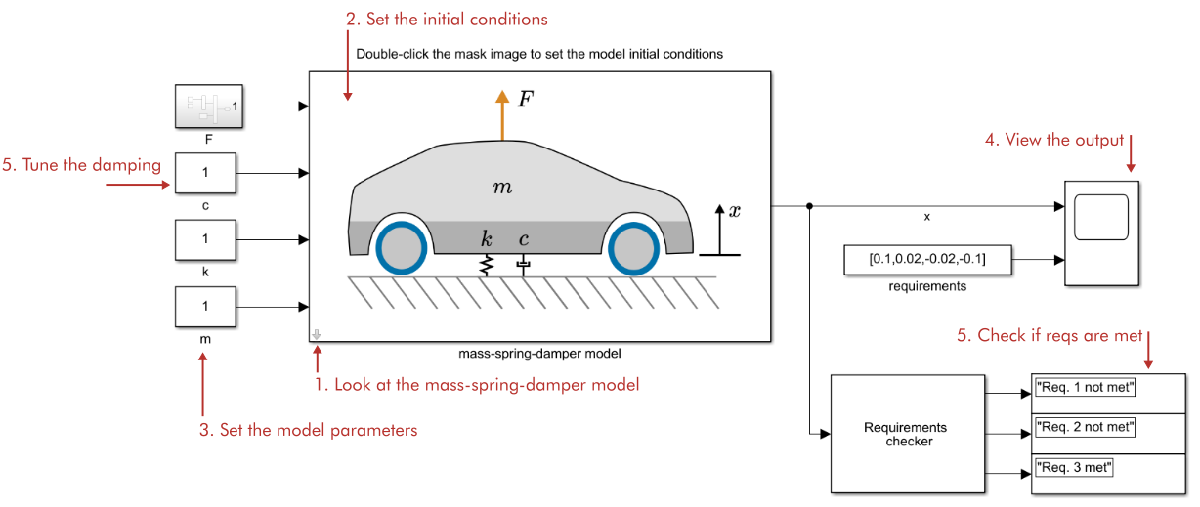

*Simulinkモデルの模式図とタスクを実行すべき場所の説明*

### 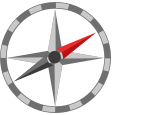**Further exploration（更なる探求）**

実際には、自動車のサスペンションシステムは、1つのバネマスダンパーよりも複雑である。このモデルを簡単に改良するには、2つのマス・スプリング・ダンパーを使用する。1つはフロント・サスペンション用、もう1つはリア用である。この手法の詳細については、Simulinkドキュメントの[automotive suspension](https://www.mathworks.com/help/simulink/slref/automotive-suspension.html)を参照すること。

**Helper functions**

これらの関数は解答のチェックとアニメーションを作成する。

function checkSyms
    varList = ["x","x_dot","x_ddot","m","c","k","F"];
    for k = 1:length(varList)
       varExists = evalin("caller",strcat("exist('",varList(k),"','var')"));
       if(varExists)
           varSym = evalin("caller",strcat("isequal(class(",varList(k),"),""sym"")"));
           if(varSym)
              disp(strcat("Success! ",varList(k)," is symbolic."))
           else
              warning(strcat(varList(k)," exists but is not symbolic.")) 
           end
       else
         warning(strcat(varList(k)," does not exist!"))
       end
    end
end

function correct = isEqualCheck(userSubmission,correctAnswer)
    correct = true;
    if( isequal(userSubmission,correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

function checkMSDeq(msdEqUser)
    syms x x_dot x_ddot m c k F
    msdEq = m*x_ddot + c*x_dot + k*x == F;
    isEqualCheck(solve(msdEqUser,x_ddot), solve(msdEq,x_ddot));
end

function checkMSDSolve(sltnUser)
    syms x x_dot x_ddot m c k F
    msdEq = m*x_ddot + c*x_dot + k*x == F;
    sltn = solve(msdEq,x_ddot);
    isEqualCheck(sltnUser,sltn);
    end

function checkFirstOrder(xSltnUser)
    syms t;
    xSltn = 10*exp(-t);
    correct = isEqualCheck(xSltnUser,xSltn);
    if(correct)
        tvec = linspace(0,10,500);
        figure("position",[1 1 400 200])
        plot(tvec,10*exp(-tvec))
        xlabel("$t$","Interpreter","latex")
        ylabel("$x(t)$","Interpreter","latex")
        title("Solution curve")
    end
end

function animateMSD(tin,xin,spacingMultiplier,steps)
    
    Nmass = size(xin,2); % Number of masses

    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 1; % Mass width
    h = 2; % Height of masses
    y = 0; % Vertical position
    
    % Local variables
    t = linspace(tin(1),tin(end),steps);
    x = zeros(steps,Nmass);
    for k = 1:Nmass
        x(:,k) = interp1(tin,xin(:,k),t);
    end
    spacing = 2*max(abs(x),[],"all")*spacingMultiplier;
    xmax = spacing*2.5 + 2;
    
    % Loop to create the animation
    figure;    
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        x0k = 0;
        for k = 1:Nmass
            % Plot springs
            xc = spacing*k+x(j,k)-w/2;       
            xs = linspace(x0k,xc,12);
            ys = 0.25*(-1).^(1:numel(xs));
            plot(xs,ys + 0.5,"k");
            % Plot dampers
            yd = 1.65;
            xd = x0k + (xc-x0k)*0.5+0.1;
            xd2 = x0k + (xc-x0k)*0.5;
            xd3 = x0k + (xc-x0k)*0.5 + 0.2;
            plot([x0k,xd,NaN,xd,xd],[yd,yd,NaN,yd-0.1,yd+0.1],"k")
            plot([xd2,xd3,NaN,xd2,xd3,NaN,xd3,xd3,NaN,xd3,xc],[yd-0.15,yd-0.15,NaN,yd+0.15,yd+0.15,NaN,yd-0.15,yd+0.15,NaN,yd,yd],"k")
            % Update position
            x0k = xc + w;
            % Plot masses
            x1 = spacing*k + x(j,k) - 0.5;
            rectangle("Position",[x1 y w h],"FaceColor",colors(k,:))
            text(x1 + w/2, h/2,"m_" + num2str(k),"HorizontalAlignment","center","color","w")
            % Plot x1, x2 distances
            quiver(spacing*k, y+h*1.1, x(j,k),0,"k-","MaxHeadSize",1/(x(j,k))^2)
            plot([1;1]*[spacing*k, spacing*k+x(j,k)],[0.95;1.05]*(y*[1,1]+h*1.1),"k-","markersize",12)
            text((spacing*k + spacing*k+x(j,k) )/2,(y+h*1.3),"x_"+num2str(k),"HorizontalAlignment","Center")
        end
        hold off
        axis([0,xmax,-1,3])
        set(gca,"ytick",[])
        xlabel("reference axis [m]")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x [m]")
        hold off
        box off
        drawnow
    end
end

function addModelPaths()
    % Adds the paths for the models and images
    scriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
    addpath(scriptPath,scriptPath + "/images/",scriptPath + "/models/")
end

% Suppress unused suggestions
%#ok<*UNRCH> 
